clear; close; clc;
load('Repeated_Visit_Snapshot_Data.mat')

Truncate = true

Truncate = logical
   1


truncationThreshold = 4;

X = firstVisitData;
Xprime = secondVisitData;

dt = 1;

[U, Sigma, V] = svd(X,"econ");

% truncate the svd if desired
if Truncate == true
    r = length(find(diag(Sigma) > truncationThreshold));
else
    r = length(diag(Sigma));
end

% apply trucnation
Ur = U(:,1:r);
Sigmar = Sigma(1:r ,1:r);
Vr = V(:,1:r);


## Do POD while we are here

podModes = V;
podTimeCoeffs = X*V;
eigvals = diag(Sigma).^2;

## Aproximate A matrix and Dynamic modes

A_tilde = Ur' * Xprime * Vr / Sigmar; %calcilate matrix A tilde to aprox time advaning matrix A

discreteTimeEigVals = eig(A_tilde); % eigvalues of A_tilde are the same as eig vals of A
modes = Xprime * Vr / Sigmar * diag(discreteTimeEigVals); %exact dmd modes
contTimeEigVals = log(discreteTimeEigVals)/dt; %continuous time eig vals

## Analysis

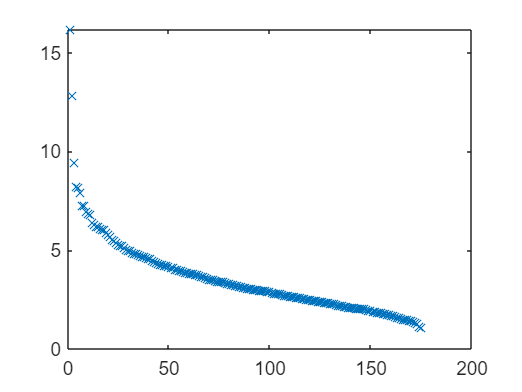

plot(diag(Sigma),"x")

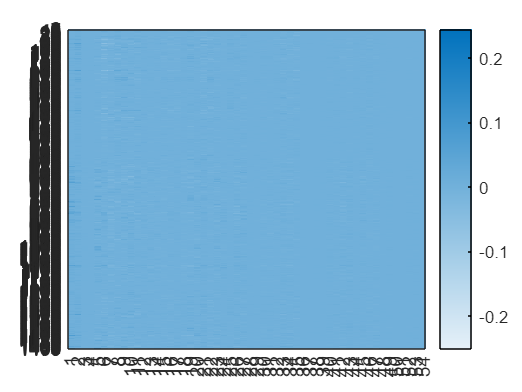

heatmap(real(modes)); grid off;

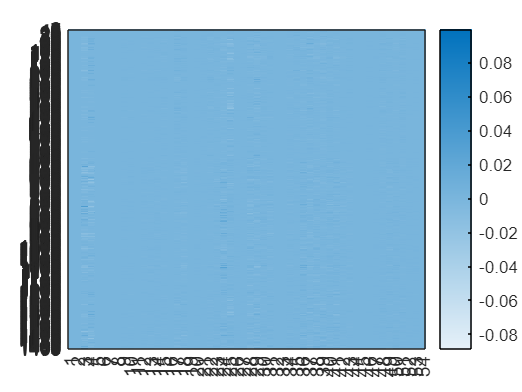

heatmap(imag(modes)); grid off;

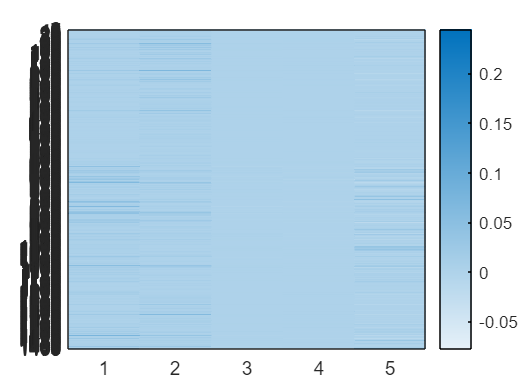

heatmap(real(modes(:,1:5))); grid off;

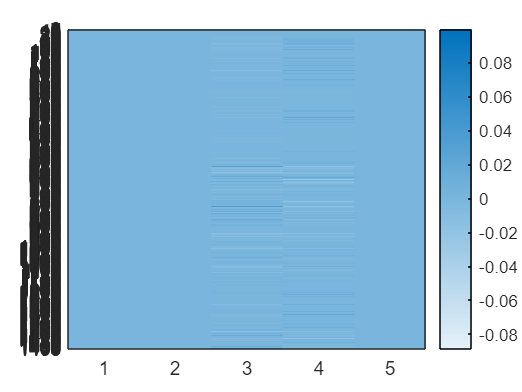

heatmap(imag(modes(:,1:5))); grid off;

## Plot POD

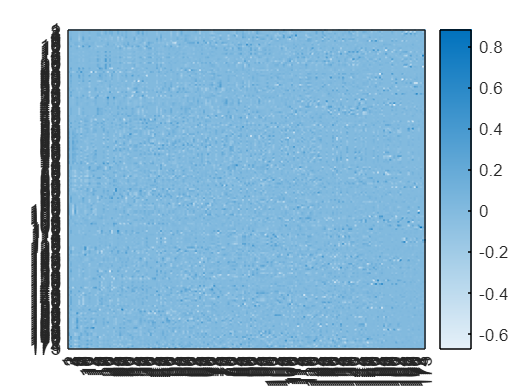

heatmap(podModes); grid off;

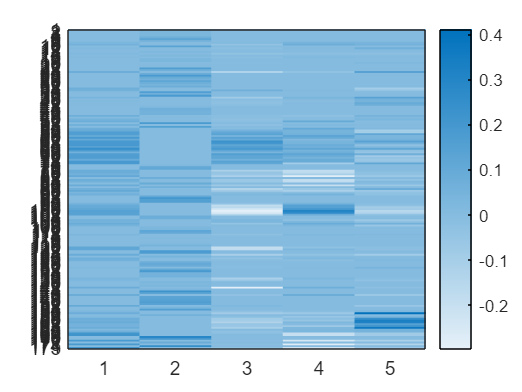

heatmap(podModes(:,1:5)); grid off;

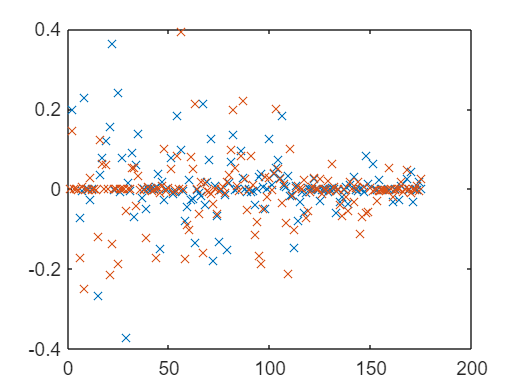

plot(podTimeCoeffs(1:2,:)',"x")

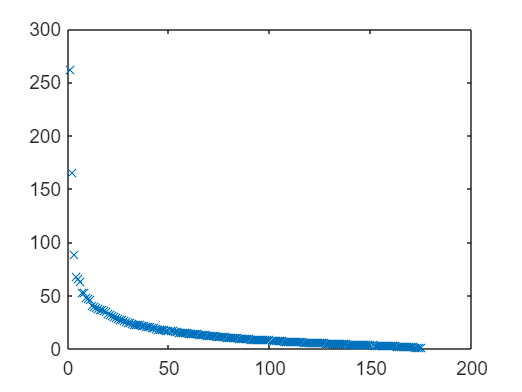

plot(eigvals,"x")

## decode mode


%modeOfIntrest = podModes(:,1)
modeOfIntrest = modes(:,1)'

modeOfIntrest =     0.0000    0.0000    0.0000    0.0061    0.0000    0.0009    0.0000         0    0.0045         0         0    0.0000    0.0000    0.0000         0    0.0000         0         0    0.0000    0.0000    0.0028    0.0000         0         0    0.0000    0.0000         0    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000         0    0.0044    0.0057    0.0000         0         0    0.0000    0.0000         0         0    0.0078    0.0340    0.0000    0.0000    0.0570    0.0000


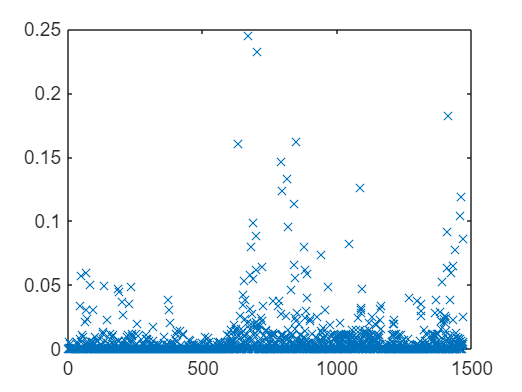



plot(sort(modeOfIntrest,1,"descend"),"x")

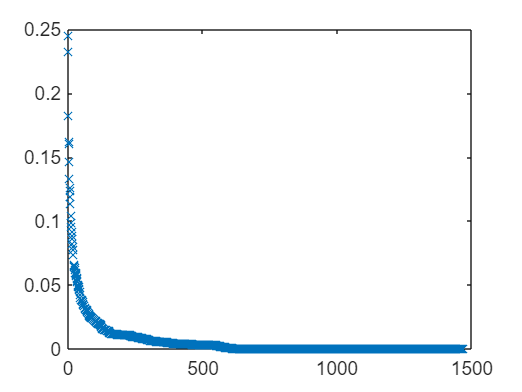

plot(sort(modeOfIntrest,2,"descend"),"x")



biggest = maxk(modeOfIntrest,10)

biggest =     0.2446    0.2325    0.1821    0.1623    0.1603    0.1464    0.1332    0.1260    0.1236    0.1195


%biggest = mink(modeOfIntrest,10)

keyDiagnoses = zeros(length(biggest),1)

keyDiagnoses =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for i = 1:length(biggest)
    keyDiagnoses(i) = find(modeOfIntrest == biggest(i));
end

keyDiagnoses

keyDiagnoses =          669
         704
        1411
         849
         632
         794
         814
        1087
         797
        1460



inputData = readcell("diagnoses_icd.csv") % Read Data

inputData = 4507×5 cell array
    {'subject_id'}    {'hadm_id' }    {'seq_num'}    {'icd_code'}    {'icd_version'}
    {[  10035185]}    {[22580999]}    {[      3]}    {[    4139]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[     10]}    {'V707'    }    {[          9]}
    {[  10035185]}    {[22580999]}    {[      1]}    {[   41401]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      9]}    {[    3899]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[     11]}    {'V8532'   }    {[          9]}
    {[  10035185]}    {[22580999]}    {[      2]}    {[   25002]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      7]}    {[   71696]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      8]}    {'V1083'   }    {[          9]}
    {[  10035185]}    {[22580999]}    {[      4]}    {[    2724]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      6]}    {'V5867'   }    {[          9]}
    {[  10035185]}    {[22580999]} 

% convert icd codes to strings
inputData(:,3) = arrayfun( @(x) {string(x)}, inputData(:,3));

icd_codes = arrayfun( @(x) string(x), inputData(2:end,4))

icd_codes = 4506×1 string array
    "4139"
    "V707"
    "41401"
    "3899"
    "V8532"
    "25002"
    "71696"
    "V1083"
    "2724"
    "V5867"
    "27800"
    "4829"
    "99592"
    "2768"
    "388"
    "78791"
    "5601"
    "2875"
    "60001"
    "79092"
    "5110"
    "2859"
    "5849"
    "78820"
    "4240"
    "V4589"
    "5121"
    "7873"
    "99832"
    "33812"


icd_bitSet_mapping = unique(icd_codes);

keyCodes = [];

for i = 1:length(keyDiagnoses)
    keyCodes = [keyCodes; icd_bitSet_mapping(keyDiagnoses(i))];
end

keyCodes

keyCodes = 10×1 string array
    "E039"
    "E785"
    "Z794"
    "I2510"
    "C9110"
    "F329"
    "G4733"
    "N179"
    "F419"
    "Z955"



icd_codes(keyDiagnoses(4))

ans = "N189"

## reconstruct time dynamics

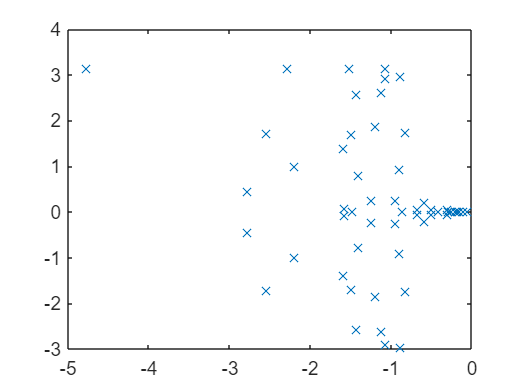

numberOfSnapshots = size(X,2) -1; % we must exclude one snapshot due to DMD needing to time shift by one

initialAmplitudes = modes\modes(:,1); %initial mode amplitudes

timeDynamics = zeros(length(contTimeEigVals), numberOfSnapshots); %initialize time dynamics to zero matrix of rank by number of snapshots
t = (0:numberOfSnapshots-1) * dt; % -2 because we start at t = 0
for i = (1:numberOfSnapshots)
    timeDynamics(:,i) = (initialAmplitudes .* exp(contTimeEigVals * t(i))); % = e^(OMEGA*t) * b (solution to a linear diff eq)
end

plot(contTimeEigVals,"x");


%reconsturct = real(modes(:,1:5)*timeDynamics(1:5,:))
reconsturct = real(modes(:,:)*timeDynamics(:,:))

reconsturct =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

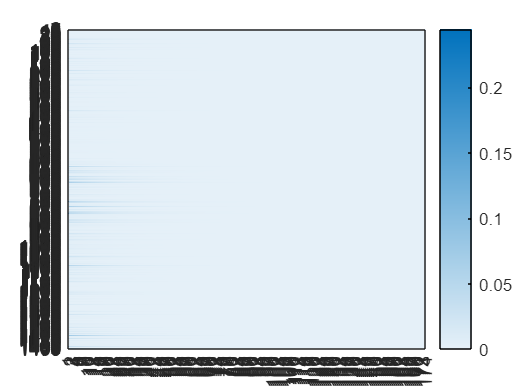

heatmap(reconsturct); grid off;

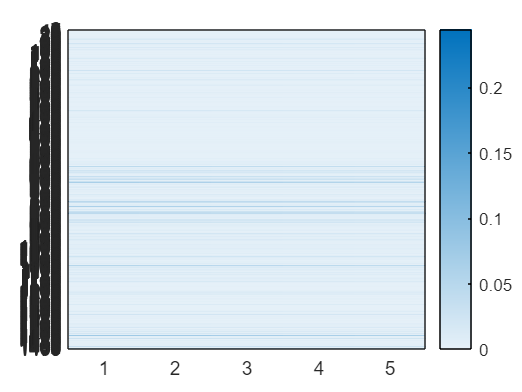

heatmap(reconsturct(:,1:5)); grid off;